# Linearized Encoding Analysis (LEA👧)

This MATLAB package is to perform linearized encodign analysis on time series data (see [Kim, 2022, Frontiers in Neuroscience](https://doi.org/10.3389/fnins.2022.928841)).

This version (v20240902) is for a tutorial at [KSMPC (Korean Society for Music Perception and Cognition) Summer School 2024 [only Korean]](https://www.ksmpc.kr/single-post/2024-%EC%A0%9C-3-%ED%9A%8C-%ED%95%9C%EA%B5%AD%EC%9D%8C%EC%95%85%EC%A7%80%EA%B0%81%EC%9D%B8%EC%A7%80%ED%95%99%ED%9A%8C-%EC%97%AC%EB%A6%84%ED%95%99%EA%B5%90). Currently, only nested leave-one-stimulus-out cross-validation is implemented. Each response unit is optimized seperately via grid search, but all stimulus features are regularized by a single lambda.

The end-user functions are:

- `lea_addpath()`: sets paths

- `lea_main()`: runs all steps

- `lea_test()`: runs unit tests with a simulated data

Other functions in the `./private/` directory are not meant to be directly called by end-users.

(CC0-BY) 2024-09-02, [seung-goo.kim@ae.mpg.de](mailto:seung-goo.kim@ae.mpg.de)

## SETTING UP PATHS

clear
close all
addpath('../sgfunc/')
lea_addpath()

## EXAMPLE #1: Toy data

TestJob = lea_test(struct(IsFigure=false, EffectSize=2, ...
  nRands=1000, TempGaussWin=10, DelaysSmp=(0:3), ...
  IsTest=true, RelToiSec=[10 -10]));

          IsFigure: 0
        EffectSize: 2
            nRands: 1000
      TempGaussWin: 10
         DelaysSmp: [0 1 2 3]
            IsTest: 1
         RelToiSec: [10 -10]
          nSamples: 50
         nFeatures: 2
        nResponses: 3
             nSets: 4
    SamplingRateHz: 1
        LambdaGrid: [1.0000e-05 3.1623e-05 1.0000e-04 3.1623e-04 1.0000e-03 0.0032 0.0100 0.0316 0.1000 0.3162 1 3.1623 10 31.6228 100 316.2278 1000 3.1623e+03 10000 3.1623e+04 100000]

[runcv|2024-09-04T11:21:23] DONE: took 0.026 sec
[lea_test|2024-09-04T11:21:23] Mean Lopt =    1.0e+03 *

    0.0075    5.6234    0.0562

[lea_test|2024-09-04T11:21:23] Mean acc =     0.7010    0.3425    0.1366

[randtest|2024-09-04T11:21:24] DONE: took 1.213 sec
[lea_test|2024-09-04T11:21:24] ALL PASSED!


          IsFigure: 1
        EffectSize: 2
            nRands: 1000
      TempGaussWin: 10
         DelaysSmp: [0 1 2 3]
            IsTest: 0
         RelToiSec: [10 -10]
          nSamples: 50
         nFeatures: 2
        nResponses: 3
             nSets: 4
    SamplingRateHz: 1
        LambdaGrid: [1.0000e-05 3.1623e-05 1.0000e-04 3.1623e-04 1.0000e-03 0.0032 0.0100 0.0316 0.1000 0.3162 1 3.1623 10 31.6228 100 316.2278 1000 3.1623e+03 10000 3.1623e+04 100000]

[runcv|2024-09-04T11:21:25] DONE: took 0.012 sec
[lea_test|2024-09-04T11:21:25] Mean Lopt =    1.0e+04 *

    0.0002    1.3335    2.3714

[lea_test|2024-09-04T11:21:25] Mean acc =     0.8239    0.1635   -0.0901

[randtest|2024-09-04T11:21:25] DONE: took 0.965 sec


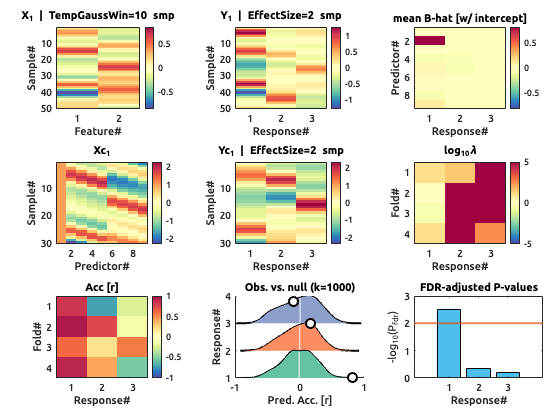

TestJob = lea_test(struct(IsFigure=true, EffectSize=2, ...
  nRands=1000, TempGaussWin=10, DelaysSmp=(0:3), ...
  IsTest=false, RelToiSec=[10 -10]));

## EXAMPLE #2: Real data

For the sake of demonstration, let's say we have time series of a stimulus feature [audio envelope] and responses [subject-averaged online ratings of '*Feeling Moved or Touched'* and '*Perceived Beauty'* ]. Both are down-sampled 

This data is from Vuoskoski et al., (2022) [[https://doi.org/10.1371/journal.pone.0261151](https://doi.org/10.1371/journal.pone.0261151)] and available from Open Science Framework [[https://osf.io/xgj85/](https://osf.io/xgj85/)].

### Visual inspection of data

The acceptable data format requires:

- Time stamps in seconds in the first column

- Values in the second column

- One header row

- Being encoded in plain text, delimited by commas (.csv)

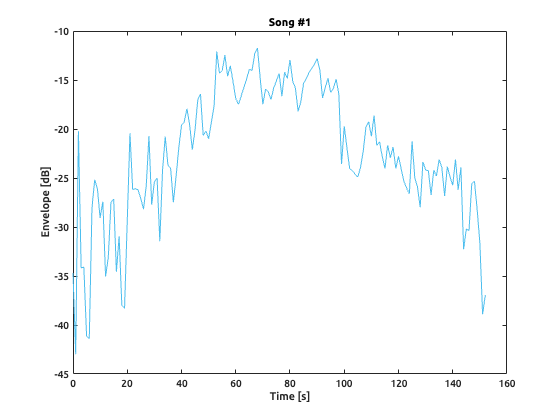

TblX = readtable('./demo/env_song1.csv');
figure; plot(TblX(:,1).Variables, TblX(:,2).Variables);
xlabel('Time [s]'); ylabel('Envelope [dB]'); title('Song #1')

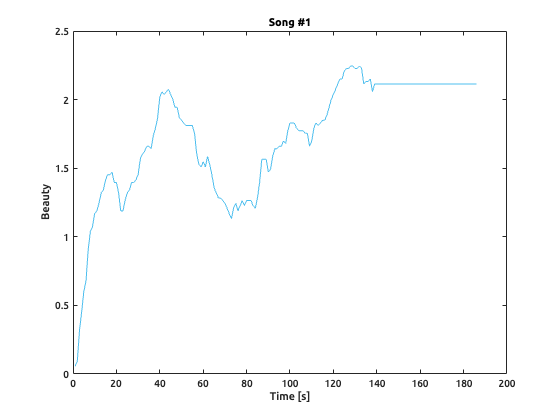

TblY = readtable('./demo/beauty_song1.csv');
figure; plot(TblY(:,1).Variables, TblY(:,2).Variables)
xlabel('Time [s]'); ylabel('Beauty'); title('Song #1')

The rating time series is not so nice... Nothing happens until 10 seconds, then also flat-lined after 140 seconds. Perhaps high-pass filtering would 

### Highpass filtering

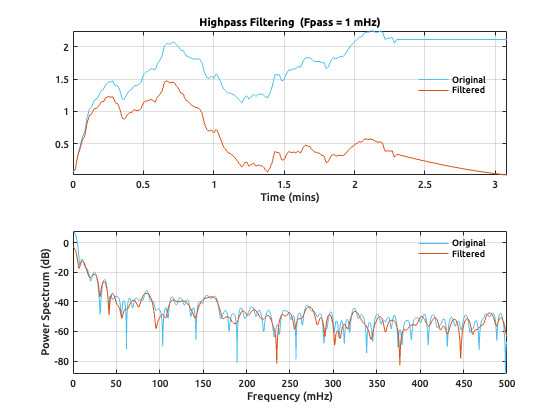

PassFreqHz = 0.001;
figure; highpass(TblX(:,2).Variables, PassFreqHz, 1);
figure; highpass(TblY(:,2).Variables, PassFreqHz, 1);

### Modeling with a single response variable

[lea_main|2024-09-04T11:21:28] START
           FnamesX: {7×1 cell}
           FnamesY: {7×1 cell}
         RelToiSec: [15 -15]
          DnameMdl: './demo/mdl1/'
         DelaysSmp: [-1 0 1 2]
        HighPassHz: 1.0000e-03
    SamplingRateHz: 1
        LambdaGrid: [1.0000e-05 3.1623e-05 1.0000e-04 3.1623e-04 1.0000e-03 0.0032 0.0100 0.0316 0.1000 0.3162 1 3.1623 10 31.6228 100 316.2278 1000 3.1623e+03 10000 3.1623e+04 100000]
            nRands: 1000

[prepdata|2024-09-04T11:21:28] DONE: took 0.525 sec
[runcv|2024-09-04T11:21:28] DONE: took 0.021 sec
[randtest|2024-09-04T11:21:29] DONE: took 1.020 sec


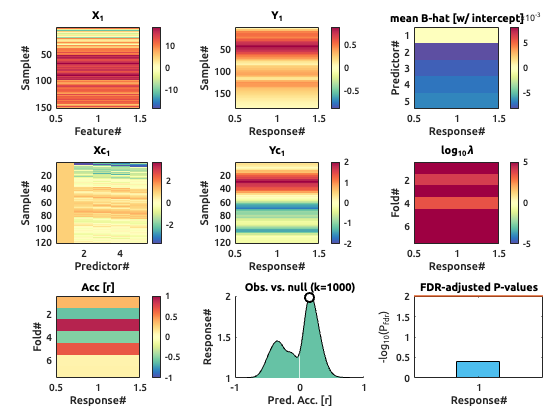

[lea_main|2024-09-04T11:21:30] END: took 1.836 sec


FnamesX = findfiles('./demo/env*');
FnamesY = [findfiles('./demo/touched*')];
Job = struct(FnamesX={FnamesX}, FnamesY={FnamesY}, RelToiSec=[15 -15], ...
  DnameMdl='./demo/mdl1/', DelaysSmp=(-1:2), HighPassHz=0.001);
[Job] = lea_main(Job);

### Modeling with two response variables

[lea_main|2024-09-04T11:21:30] START
           FnamesX: {7×1 cell}
           FnamesY: {7×2 cell}
         RelToiSec: [15 -15]
          DnameMdl: './demo/mdl2/'
         DelaysSmp: [-1 0 1 2]
        HighPassHz: 1.0000e-03
    SamplingRateHz: 1
        LambdaGrid: [1.0000e-05 3.1623e-05 1.0000e-04 3.1623e-04 1.0000e-03 0.0032 0.0100 0.0316 0.1000 0.3162 1 3.1623 10 31.6228 100 316.2278 1000 3.1623e+03 10000 3.1623e+04 100000]
            nRands: 1000

[prepdata|2024-09-04T11:21:30] DONE: took 0.753 sec
[runcv|2024-09-04T11:21:30] DONE: took 0.014 sec
[randtest|2024-09-04T11:21:32] DONE: took 1.419 sec


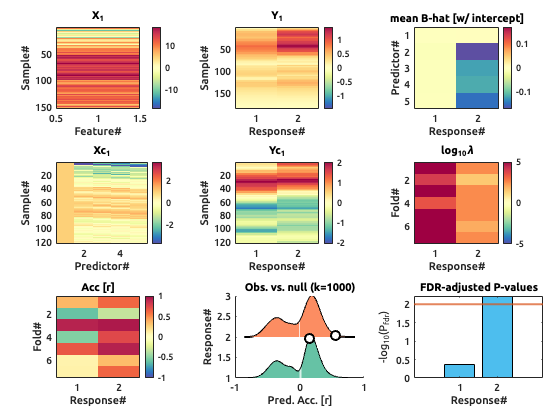

[lea_main|2024-09-04T11:21:32] END: took 2.571 sec


FnamesX = findfiles('./demo/env*');
FnamesY = [findfiles('./demo/touched*'), findfiles('./demo/beauty*')];
Job = struct(FnamesX={FnamesX}, FnamesY={FnamesY}, RelToiSec=[15 -15], ...
  DnameMdl='./demo/mdl2/', DelaysSmp=(-1:2), HighPassHz=0.001);
[Job] = lea_main(Job);